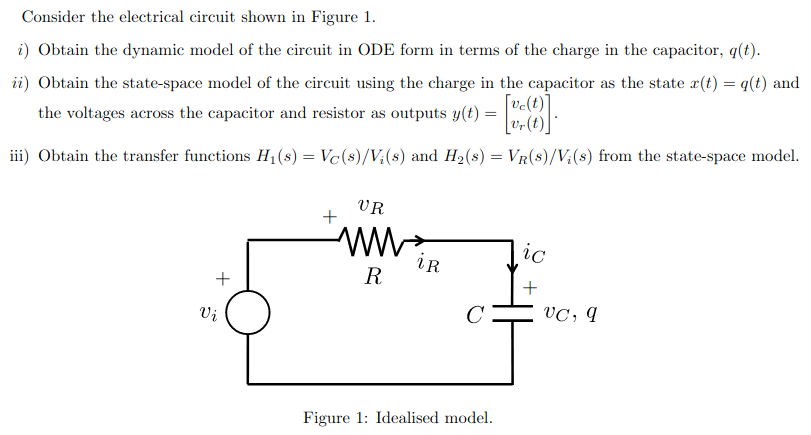

% i
syms Vi(t) R Cap q(t) Vc(t) Vr(t)

i = diff(q)

$$i(t) = \frac{\partial }{\partial t}q\left(t\right)$$

Vc = 1 / Cap * q

$$Vc(t) = \frac{q\left(t\right)}{\mathrm{Cap}}$$

Vr = R * i

$$Vr(t) = R\,\frac{\partial }{\partial t}q\left(t\right)$$

kvl = Vi == Vc + Vr

$$kvl(t) = \mathrm{Vi}\left(t\right)=R\,\frac{\partial }{\partial t}q\left(t\right)+\frac{q\left(t\right)}{\mathrm{Cap}}$$


% ii
% subs()

syms A B
C = sym('C', [2 1])

$$C = \left(\begin{array}{c} C_{1}\\ C_{2} \end{array}\right)$$

D = sym('D', [2 1])

$$D = \left(\begin{array}{c} D_{1}\\ D_{2} \end{array}\right)$$


syms dq

state_update = dq == A * q + B * Vi

$$state\_update(t) = \mathrm{dq}=B\,\mathrm{Vi}\left(t\right)+A\,q\left(t\right)$$

output = [Vc; Vr] == C * q + D * Vi

$$output(t) = \left(\begin{array}{c} \frac{q\left(t\right)}{\mathrm{Cap}}=D_{1}\,\mathrm{Vi}\left(t\right)+C_{1}\,q\left(t\right)\\ R\,\frac{\partial }{\partial t}q\left(t\right)=D_{2}\,\mathrm{Vi}\left(t\right)+C_{2}\,q\left(t\right) \end{array}\right)$$


new = subs([kvl state_update], i, dq)

$$new(t) = \left(\begin{array}{cc} \mathrm{Vi}\left(t\right)=R\,\mathrm{dq}+\frac{q\left(t\right)}{\mathrm{Cap}} & \mathrm{dq}=B\,\mathrm{Vi}\left(t\right)+A\,q\left(t\right) \end{array}\right)$$

solve_for([A B], new, [R Cap])